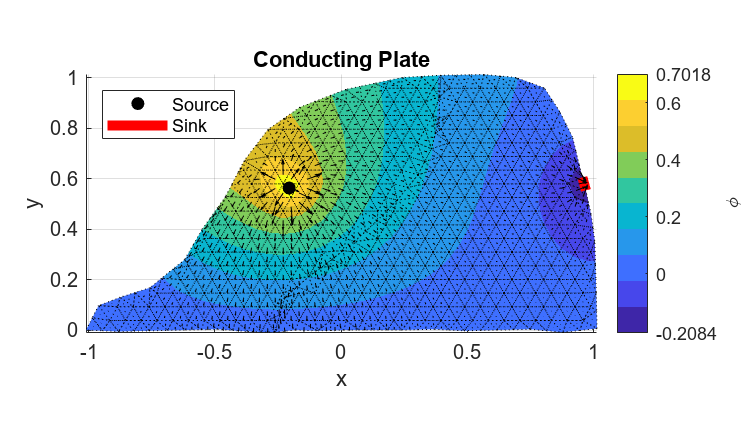

clear; close all

u = readmatrix("u.dat");
u = u(2:end);

nodes = readmatrix("hw44.nod.dat");
xNodes = nodes(1:502, 2);
yNodes = nodes(1:502, 3);
elemsJunk = readmatrix("hw44.ele.dat");
elems = elemsJunk(:, 2:4);

%%Point Source
sourceCoor = [-0.206052 0.56379];

%%Point Sink
sinkCoor = [0.969118 0.554412; 0.955882 0.605883];

Vec = -readmatrix("grad.dat");
%Vec = zeros(size(elems,1),2);
f = figure;
Plot2dTriMesh(xNodes, yNodes, elems, u, Vec);
plot(sourceCoor(1), sourceCoor(2), 'ko', 'MarkerSize', 6, 'MarkerFaceColor',"k")
plot(sinkCoor(:, 1), sinkCoor(:, 2),  'r-', 'MarkerFaceColor',"w", "LineWidth", 5)
title('Conducting Plate')
c = colorbar;
set(c,'YTick',[min(u),-0.0:0.2:0.6,max(u)])
c.Label.String = "$\phi$";
c.Label.Interpreter = "latex";
legend("", "", 'Source', 'Sink', 'Location','northwest')
exportgraphics(gcf, 'Plate.png', 'Resolution',300);


u2 = readmatrix("uMAT.dat")

u2 =     0.0000
   -0.0000
    0.0146
    0.0000
    0.0179
         0
    0.0110
    0.0392
    0.0300
   -0.0000


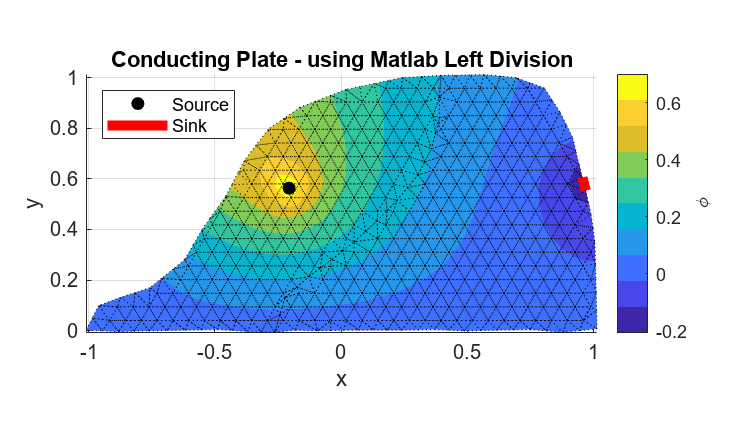

f = figure;
Plot2dTriMesh(xNodes, yNodes, elems, u2);
plot(sourceCoor(1), sourceCoor(2), 'ko', 'MarkerSize', 6, 'MarkerFaceColor',"k")
plot(sinkCoor(:, 1), sinkCoor(:, 2),  'r-', 'MarkerFaceColor',"w", "LineWidth", 5)
title('Conducting Plate - using Matlab Left Division')
c = colorbar;
c.Label.String = "$\phi$";
c.Label.Interpreter = "latex";
legend("", 'Source', 'Sink', 'Location','northwest')
exportgraphics(gcf, 'Plate2.png', 'Resolution',300);

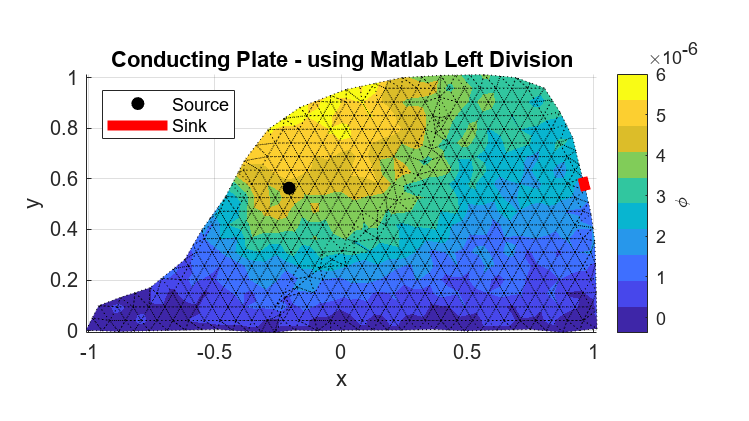


udiff = u2 - u;
f = figure;
Plot2dTriMesh(xNodes, yNodes, elems, udiff);
plot(sourceCoor(1), sourceCoor(2), 'ko', 'MarkerSize', 6, 'MarkerFaceColor',"k")
plot(sinkCoor(:, 1), sinkCoor(:, 2),  'r-', 'MarkerFaceColor',"w", "LineWidth", 5)
title('Conducting Plate - using Matlab Left Division')
c = colorbar;
c.Label.String = "$\phi$";
c.Label.Interpreter = "latex";
legend("", 'Source', 'Sink', 'Location','northwest')
exportgraphics(gcf, 'PlateDiff.png', 'Resolution',300);

CovUI = readmatrix("CovU_I.dat");
CovBI = readmatrix("CovB_I.dat");
CovUII = readmatrix("CovU_II.dat")

CovUII =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0

CovBII = readmatrix("CovB_II.dat")

CovBII =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0    

CovUIII = readmatrix("CovU_IIIB.dat")

CovUIII =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0    0.2500    0.2441    0.2353    0.2454    0.2367    0.2298    0.2287    0.2233    0.2226    0.2339    0.2315    0.2199    0.2141    0.2180    0.2181    0.2110    0.2146    0.2159    0.2189    0.2210    0.2125    0.2048    0.1967    0.2048    0.2105    0.2149    0.2116    0.1985    0.2050    0.2109    0.2019    0.2065    0.2018    0.1963    0.1909    0.1774    0.1905    0.2004    0.2038    0.1859    0.1934    0.2032    0.1862    0.1903    0.1889    0.1859    0.1822    0.178

CovBIII = readmatrix("CovB_IIIB.dat")

CovBIII =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0    0.2500    0.2441         0    0.2454         0    0.2298         0         0         0    0.2339         0         0    0.2141         0         0         0         0         0    0.2189         0         0         0    0.1967         0         0         0         0         0         0         0    0.2019         0         0         0         0    0.1774         0         0         0         0         0         0    0.1862         0         0         0         0         


CovU = CovUI + CovUII + CovUIII;
CovU = CovU(2:end, 2:end);
diagCovU = sqrt(spdiags(CovU, 0))

diagCovU =     0.5000
    0.5000
    0.4760
    0.5000
    0.4755
    0.5000
    0.4773
    0.4535
    0.4564
    0.5000



CovB = CovBI + CovBII + CovBIII;
CovB = CovB(2:end, 2:end);
diagCovB = sqrt(spdiags(CovB, 0))

diagCovB =     0.5000
    0.5000
         0
    0.5000
         0
    0.5000
         0
         0
         0
    0.5000


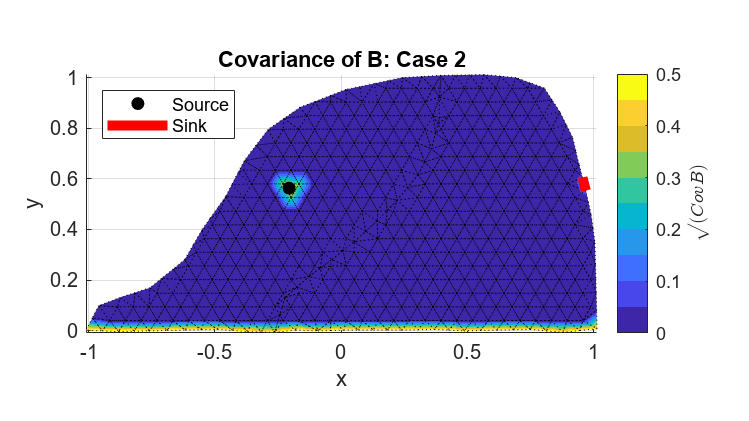


f = figure;
Plot2dTriMesh(xNodes, yNodes, elems, diagCovB);
plot(sourceCoor(1), sourceCoor(2), 'ko', 'MarkerSize', 6, 'MarkerFaceColor',"k")
plot(sinkCoor(:, 1), sinkCoor(:, 2),  'r-', 'MarkerFaceColor',"w", "LineWidth", 5)
title('Covariance of B: Case 2')
c = colorbar;
c.Label.String = '$\sqrt(CovB)$';
c.Label.Interpreter = "latex";
legend("", 'Source', 'Sink', 'Location','northwest')
exportgraphics(gcf, 'IIII_B.png', 'Resolution',300);

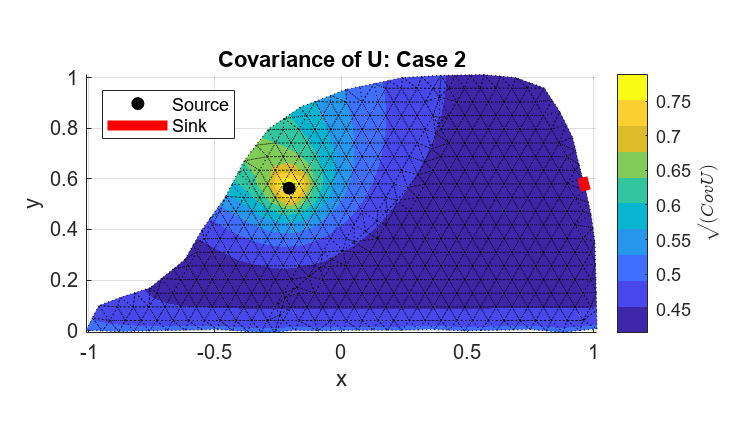



f = figure;
Plot2dTriMesh(xNodes, yNodes, elems, diagCovU);
plot(sourceCoor(1), sourceCoor(2), 'ko', 'MarkerSize', 6, 'MarkerFaceColor',"k")
plot(sinkCoor(:, 1), sinkCoor(:, 2),  'r-', 'MarkerFaceColor',"w", "LineWidth", 5)
title('Covariance of U: Case 2')
c = colorbar;
c.Label.String = '$\sqrt(CovU)$';
c.Label.Interpreter = "latex";
legend("", 'Source', 'Sink', 'Location','northwest')
exportgraphics(gcf, 'IIII_U.png', 'Resolution',300);